# Unidad Profesional Interdiciplinaria en Ingeniería y Tecnologías Avanzadas

   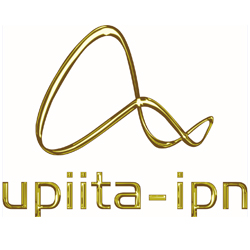

# P08: Sistemas diferenciales

### Integrantes

- Arce Rodríguez Aransa Ximena

- Jiménez Velázquez Ana Brenda

- Pacheco Muñoz Jennifer

### Objetivos

- Calcular la funciones de tranferencia

-  Identificar  los componentes de la respuesta de un sistema diferencial

- Identificar las respuesta a sistemas diferenciales para diversas entradas 

### Desarrollo

Se tiene $$\ddot{y}(t)+3\dot{y}(t)+3y(t)=-\dot{x}(t)+x(t)$$ donde $ $x(t)=cos(2t)u(t), y(0^-)=1, \dot{y}(0^-)=1$$

#### 1. Muestra la función de transferencia del sistema

syms t
sympref('HeavisideAtOrigin', 1);
 
a = [3 3 1];
b = [1 -1];
ciy = [1 1];
xi = cos(2*t)*heaviside(t);
t0 = 10;
f_transferencia(a,b)

P(s) es igual a:

1 - s

Q(s) es igual a:

 2

s  + 3 s + 3

La funcion de transferencia H(s) es igual a:

      s - 1

- ------------

   2

  s  + 3 s + 3

#### 2. Muestra la respuesta al impulso (simbólico, gráfica)

entrada_impulso(a,b,ciy,t0)

APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

X(s) - s X(s)

SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

1 - s

DESPEJAMOS Y(s)

Y(s)=

      5

------------

 2

s  + 3 s + 3

DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)

Y(s)=

      5

------------

 2

s  + 3 s + 3

Aplicamos transformada inversa, asi la solución es

y(t)=

           /   3 t \    / sqrt(3) t \

sqrt(3) exp| - --- | sin| --------- | 10

           \    2  /    \     2     /

----------------------------------------

                    3

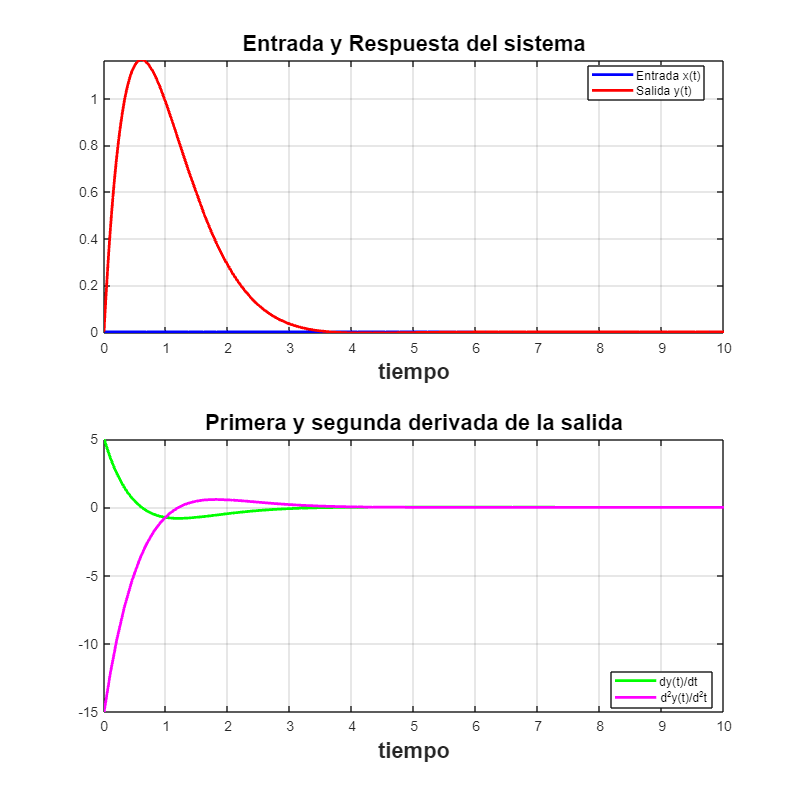

#### 3. Muestra la respuesta a entrada cero (simbólico, gráfica)

syms t
a = [3, 3, 1];          % Coeficientes de las derivadas de y(t)
b = [-1, 1];            % Coeficientes de las derivadas de x(t)
ciy = [1, 1];           % Condiciones iniciales de y(t)
xi = 0;  % Función de entrada x(t)
t0 = 10;                % Tiempo final para graficar la solución
 
entrada(a, b, ciy, xi, t0)
 

APLICAMOS TRANSFORMADA DE LAPLACE y substituimos condiciones iniciales

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

s X(s) - X(s)

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

0

Y(s) =

    s + 4

------------

 2

s  + 3 s + 3

DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)

Y(s) =

    s + 4

------------

 2

s  + 3 s + 3

Aplicamos transformada inversa, así la solución es

y(t) =

             /                               / sqrt(3) t \   \

             |                    sqrt(3) sin| --------- | 5 |

   /   3 t \ |    / sqrt(3) t \              \     2     /   |

exp| - --- | | cos| --------- | + -------------------------- |

   \    2  / \    \     2     /                3             /

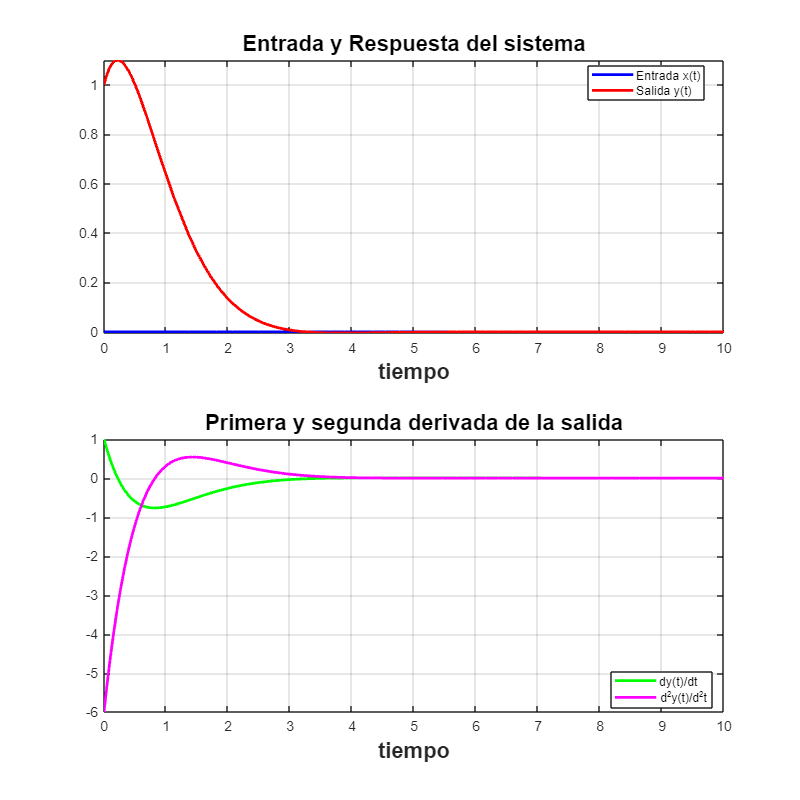

#### 4. Muestra la respuesta a estado cero (simbólico, gráfica) 

syms t
a = [3, 3, 1];          % Coeficientes de las derivadas de y(t)
b = [1, -1];            % Coeficientes de las derivadas de x(t)
ciy = [1, 1];           % Condiciones iniciales de y(t)
xi = cos(2*t)*heaviside(t);  % Función de entrada x(t)
t0 = 10;                % Tiempo final para graficar la solución
 
estado(a, b, [0 0] , xi, t0)
 

APLICAMOS TRANSFORMADA DE LAPLACE y sustituimos condiciones iniciales

                     2

3 Y(s) + 3 s Y(s) + s  Y(s)

=

X(s) - s X(s)

SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA

                     2

3 Y(s) + 3 s Y(s) + s  Y(s)

=

            2

   s       s

------ - ------

 2        2

s  + 4   s  + 4

DESPEJAMOS Y(s)

Y(s)=

            s (s - 1)

- ----------------------------

   4      3      2

  s  + 3 s  + 7 s  + 12 s + 12

Aplicamos transformada inversa, así la solución es

y(t)=

                                        /                               / sqrt(3) t \    \

                                        |                    sqrt(3) sin| --------- | 17 |

                              /   3 t \ |    / sqrt(3) t \              \     2     /    |

                           exp| - --- | | cos| --------- | - --------------------------- | 13

sin(2 t) 4   cos(2 t) 13      \    2  / \    \     2     /                13             /

---------- - ----------- + ------------------------------------------------------------------

    37            37                                       37

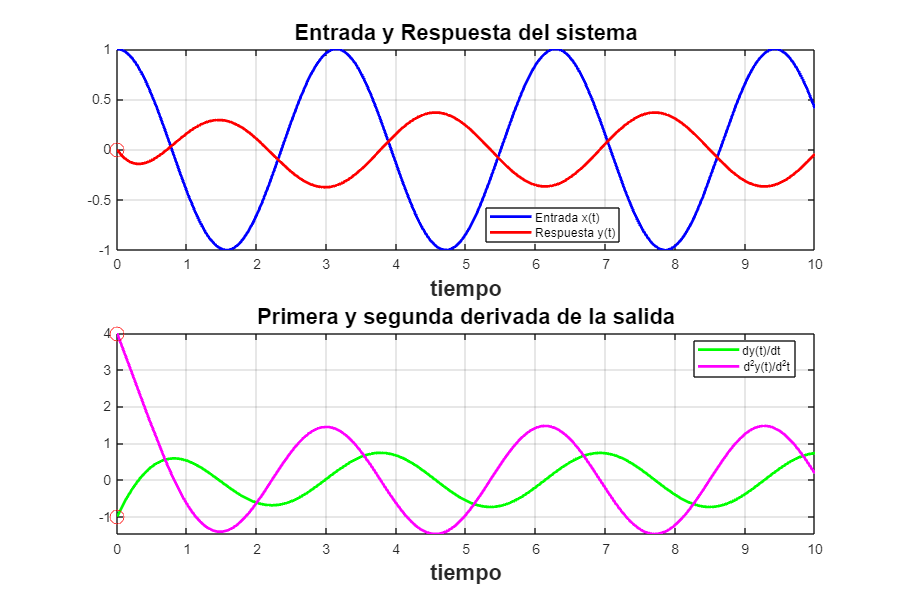

#### 5. Muestra la respuesta total (simbólico, gráfica)

syms t;
laplaceJ([3 3 1],[1 1],[1 1],cos(2*t)*heaviside(t),10)
 

APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

X(s) + s X(s)

SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA

                         2

3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=

            2

   s       s

------ + ------

 2        2

s  + 4   s  + 4

DESPEJAMOS Y(s)

Y(s)=

   3      2

  s  + 5 s  + 5 s + 16

-----------------------

  2        2

(s  + 4) (s  + 3 s + 3)

DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)

Y(s)=

11 s   16    26 s   136

---- + --    ---- + ---

 37    37     37     37

--------- + ------------

   2         2

  s  + 4    s  + 3 s + 3

Aplicamos transformada inversa, asi la solución es

y(t)=

                                        /                               / sqrt(3) t \    \

                                        |                    sqrt(3) sin| --------- | 97 |

                              /   3 t \ |    / sqrt(3) t \              \     2     /    |

                           exp| - --- | | cos| --------- | + --------------------------- | 26

cos(2 t) 11   sin(2 t) 8      \    2  / \    \     2     /                39             /

----------- + ---------- + ------------------------------------------------------------------

     37           37                                       37

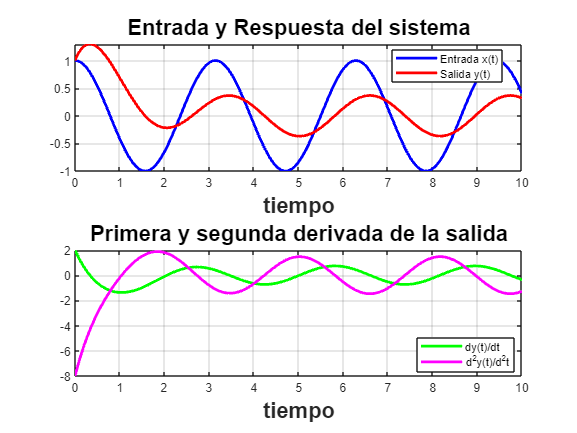

#### 6. La respuesta total al escalón con condiciones iniciales 0 (simbólico, gráfica)

syms t
escalon([1 3 3],[1],10)
 

APLICAMOS TRANSFORMADA DE FOURIER

          2

Y(w) - 3 w  Y(w) + w Y(w) 3i

=

X(w)

SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA

          2

Y(w) - 3 w  Y(w) + w Y(w) 3i

=

              1i

pi dirac(w) - --

               w

DESPEJAMOS Y(w)

Y(w)=

               1i

 pi dirac(w) - --

                w

-----------------

     2

- 3 w  + w 3i + 1

DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(w)

Y(w)=

  1i   3 - pi dirac(w) + w 3i

- -- - ----------------------

   w           2

          - 3 w  + w 3i + 1

Aplicamos transformada inversa, asi la solución es

y(t)=

             /                                                 /      1 \                          /      1 \                  \

pi + sqrt(3) | - pi #1 dirac(t) 2i + pi #2 dirac(t) 2i + pi #1 | #3 + - | (sign(t) + 1) 1i + pi #2 | #3 - - | (sign(t) + 1) 1i | + pi sign(t) - sqrt(3) (pi #1 (sign(t) + 1) 1i - pi #2 (sign(t) + 1) 1i)

             \                                                 \      2 /                          \      2 /                  /

---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

                                                                                                   2 pi

where

            /   t (sqrt(3) - 3i) 1i \

   #1 == exp| - ------------------- |

            \            6          /

            / t (sqrt(3) + 3i) 1i \

   #2 == exp| ------------------- |

            \          6          /

         sqrt(3) 1i

   #3 == ----------

              6